fname = 'Pilot3_results.json';
fid = fopen(fname);
raw = fread(fid,inf);
str = char(raw');
fclose(fid);
result = jsondecode(str);

for j = 1:length(result.Batches)
    for i = 1:length(result.Batches(j).Trials)
        trialNumber = result.Batches(j).Trials(i).TrialNumber;
        DisplayTarget = result.Batches(j).Trials(i).DisplayTarget;
        video = result.Batches(j).Trials(i).Video;
        mouseResponse = result.Batches(j).Trials(i).Response.MouseResponse;
        responseTime = result.Batches(j).Trials(i).Response.ResponseTime;
        disp(j + ", " + trialNumber + ", " + DisplayTarget + ", " + video + ", " + mouseResponse + ", " + responseTime)
    end
end

1, 1, VR, beep_video13, 0, 5.6163
1, 2, VR, beep_video12, 1, 20.7018
1, 3, VR, beep_video8, 0, 3.1153
1, 4, VR, beep_video7, 1, 4.3359
1, 5, VR, beep_video10, 0, 2.2935
1, 6, VR, beep_video5, 1, 3.9841
1, 7, VR, beep_video6, 1, 2.4366
1, 8, VR, beep_video11, 0, 2.8405
1, 9, VR, beep_video11, 0, 3.0551
1, 10, VR, beep_video6, 1, 1.7075
1, 11, VR, beep_video9, 0, 2.1401
1, 12, VR, beep_video9, 0, 2.8123
1, 13, VR, beep_video5, 1, 10.7491
1, 14, VR, beep_video9, 0, 2.3997
1, 15, VR, beep_video6, 1, 2.1143
1, 16, VR, beep_video12, 1, 2.0372
1, 17, VR, beep_video11, 0, 1.9161
1, 18, VR, beep_video5, 1, 1.7169
1, 19, VR, beep_video12, 1, 2.6438
1, 20, VR, beep_video9, 0, 2.1126
1, 21, VR, beep_video7, 1, 2.5441
1, 22, VR, beep_video6, 1, 1.717
1, 23, VR, beep_video12, 1, 2.5195
2, 1, VR, violin_video8, 1, 5.3917
2, 2, VR, violin_video13, 1, 1.8688
2, 3, VR, violin_video11, 0, 3.9014
2, 4, VR, violin_video10, 0, 3.9333
2, 5, VR, violin_video7, 0, 2.8735
2, 6, VR, violin_video6, 1, 2.7943
2, 7

HistResults = zeros(9,2,2);


participant = 1;
%beep
for j = [2,4]
    for i = 1:length(result.Batches(j).Trials)
        video = result.Batches(j).Trials(i).Video;
        response = result.Batches(j).Trials(i).Response.MouseResponse;
        regexPattern = "\d{1,2}";
        videoNumberString = regexp(video,regexPattern,'match');
        videoNumber = str2num(videoNumberString{1});
        videoNumber = videoNumber - 4;
        

        if (response == 0)
            HistResults(videoNumber, 1, participant) = HistResults(videoNumber, 1, participant) + 1;
        end
    end
end
%violin
for j = [1,3]
    for i = 1:length(result.Batches(j).Trials)
        video = result.Batches(j).Trials(i).Video;
        response = result.Batches(j).Trials(i).Response.MouseResponse;
        regexPattern = "\d{1,2}";
        videoNumberString = regexp(video,regexPattern,'match');
        videoNumber = str2num(videoNumberString{1});
        videoNumber = videoNumber - 4;
        
        if (response == 0)
            HistResults(videoNumber, 2, participant) = HistResults(videoNumber, 2, participant) + 1;
        end
    end
end

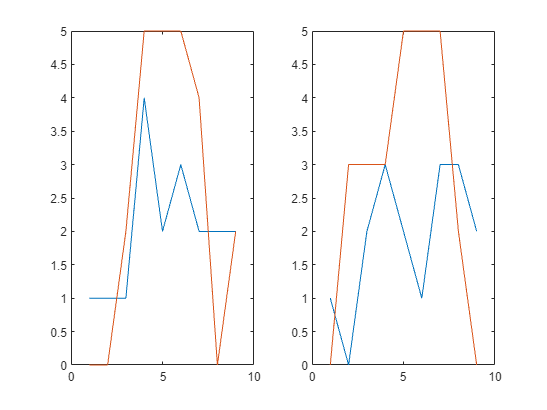

subplot(1,2,1); hold off; plot(HistResults(:,1,1)); hold on; plot(HistResults(:,1,2))
subplot(1,2,2); plot(HistResults(:,2,1)); hold on; plot(HistResults(:,2,2)); hold off